# Fminunc Trust Regions Gradient (Rosenbrock)

clc;
clear;
a=1.5;b=0;
x1 = [3.5 1]; x2 = [2.5 -1];x3 = [0.5 -1];x4 = [0.5 1];
fun = @(x)(1-x(1)+a)^2 + 100*(x(2)-b-(x(1)-a)^2)^2;
grad = @(x) [400*x(1)^3-1800*x(1)^2-400*x(1)*x(2)+2702*x(1)+600*x(2)-1355;...
    -200*x(1)^2+600*x(1)+200*x(2)-450];
fungrad = @(x) deal(fun(x),grad(x));


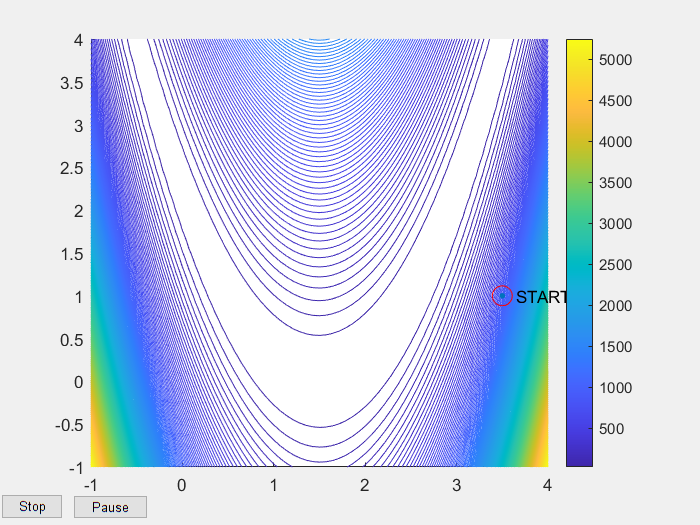

Unrecognized function or variable 'temp'.

Error in out (line 14)
        quiver(temp(1),temp(2),x(1),x(2));

Error in callAllOptimPlotFcns (line 137)
        state(i) = feval(plotNames{i},x,optimvalues,flag,varargin{:});

Error in 

% Set nondefault solver options
% options = optimoptions("fminunc","Algorithm","trust-region",...
%     "SpecifyObjectiveGradient",true,"FunctionTolerance",1e-09,"PlotFcn","optimplotlogfval");
options = optimoptions("fminunc","Algorithm","trust-region",...
    "SpecifyObjectiveGradient",true,"FunctionTolerance",1e-09,"PlotFcn",@out);

    %Tolerancja funkcji do x4
%

% Solve
[solution,objectiveValue, exitflag, output] = fminunc(fungrad,x1,options);


% Clear variables
clearvars options
format long
disp('Minimum funkcji:');disp(solution)
disp('Wartość funkcji w minimum:');disp(objectiveValue)
disp('Liczba iteracji');disp(output.iterations)
disp('Liczba wywołań funkcji celu');disp(output.funcCount)
disp('Dokładność');disp(abs(0-objectiveValue))